# **完美电磁隐身装置演示**

**        2006年，美国《科学》杂志发表了Pendry 等的论文《控制电磁场》。文中，作者首次提出了利用麦克斯韦方程组的协变性来控制电磁场的思路，并以此论文为基础，提出了变换光学（变换电磁学）的理论。由此，全球范围内关于电磁隐形的研究成为科研领域的热点。同年，杜克大学的Smith等，利用人工电磁超材料，设计并加工了第一个柱状隐形装置，发表在《科学》杂志上，并被该杂志评为当年度全球十大科技进展。与**[**球形隐身衣**](matlab:open('..\D 第四章 静态场的解法\D2_Invisibility_Cloak_in_the_journal_Science.mlx'))**的推导类似，本小节使用射线追踪的方法演示了柱形隐身衣。**

**1. 定义光线参数区间 **`tspan=[0 150]`**，以及光线的数量 **`no_lines=20`**。**

figure
tspan=[0 150];               	%定义光线参数区间
no_lines=20;             	%定义光线根数

**2. 定义了内外半径 **`a=2; b=4;`**。**

a=2;   b=4;                 	%内外半径

**3. 使用 **`linspace`** 函数生成了一组均匀分布的角度 **`phi`**。**

phi=linspace(0,2*pi,no_lines);   	%角度分布，用于判断点是否在圆内

**4. 使用 **`cylinder`** 函数生成一个半径为1，高度为1的圆柱体的坐标。**

[x,y,z]=cylinder(1);          	%高度为1，半径为1的柱面坐标

**5. 使用 **`surf`** 函数绘制隐形衣的内外表面。**

surf(a*x,a*y,8*z);            	%绘制隐形衣内部表面，半径为2，高度为8
hold on;                  	%设置为叠加绘制模式
surf(b*x,b*abs(y),8*z);         	%绘制隐形衣外表面，使用绝对值仅绘制曲面一半

**6. 设置光源位置和光照模式。**


shading interp;               
light('Position',[-1,0,0]);       	%光源位置[-1,0,0]
lighting gouraud;               	%设置光照模式为“gouraud”


**7. 设置颜色图和视角。**

colormap('Spring');         	%设置颜色图为“Spring”
view(-14,17);              	%设置视角

**8. 定义入射点的坐标。**

phi00=linspace(pi/2,3*pi/2,no_lines);	%入射点对应的角度分布
y00=b*sin(phi00);z00=linspace(0,0,no_lines); x00=b*cos(phi00); 	%入射点坐标

**9. 在一个循环中，对每一个入射点进行追踪，计算波矢初值，然后使用 **`ode45`** 函数求解哈密顿方程，得到光线的传播路径。使用 **`inpolygon`** 函数判断光线是否在隐形衣内部。**

for lp=4:length(x00)-2
    x0=x00(lp);y0=y00(lp); phi0=phi00(lp);z0=z00(lp);          	%选择入射点追踪
    nx0=-cos(phi0); ny0=-sin(phi0);nz0=0;                     	%法线方向
    c=sqrt(2);                                           	%以下定义常数
    m=(2*a*b-a^2)/b^4;                                          
    h=1+ny0^2/nx0^2-m*x0^2-m*y0^2*ny0^2/nx0^2-2*m*x0*y0*ny0/nx0;
    g=-c*(ny0^2/nx0^2)+c*m*y0^2*(ny0^2/nx0^2)+c*m*x0*y0*ny0/nx0;
    u=ny0^2/(2*nx0^2)-(1/2)*m*y0^2*(ny0^2/nx0^2)-1/2;
    kx0=(-g+sqrt(g^2-4*h*u))/(2*h);                         	%计算波矢初值
    ky0=(ny0/nx0)*(kx0-c/2);
    kz0=c/2;
    Y0=[x0 y0 z0 kx0 ky0 kz0];                    	%哈密顿方程初值
    options = odeset('RelTol',1e-10,'AbsTol',[1e-10]);        	%求解参数设置
    [T,Y] = ode45(@cylinderham,tspan,Y0,options);         	%数值求解
    IN=inpolygon(Y(:,1), Y(:,2) , [b*cos(phi)], [b*sin(phi)]);   	%判断光线是否在隐形衣内部
    tmpx=Y(:,1); tmpy=Y(:,2);tmpz=Y(:,3);                 	%光线坐标
    plot3(tmpx(IN),tmpy(IN),tmpz(IN),'b','linewidth',2); hold on; 	%绘制内部光线
end

**10. 最后，绘制了内部光线，并设置了同比例显示。**

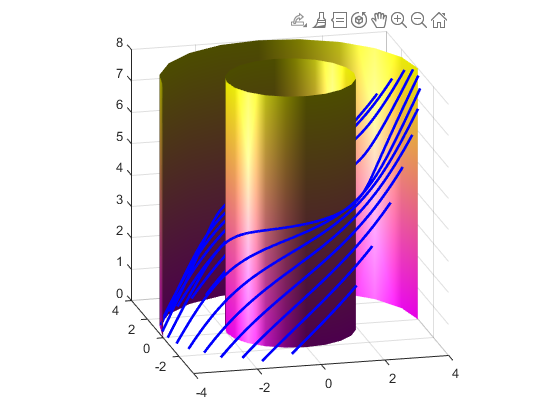

axis equal;                                    	%同比例显示
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **计算哈密顿方程组**

function dy = rayham(t,y);
dy =zeros(6,1);
a=2;b=4;                             	%内外半径数值
r=(y(1).^2+y(2).^2+y(3).^2).^(1/2);        	%球坐标系下矢径的大小
s=y(1)*y(4)+y(2)*y(5)+y(3)*y(6);    	%定义波矢与矢径的点积
dy(1) = y(4)-((2*a*r-a^2)/r^4)*s*y(1);     	%哈密顿方程组的前三个方程
dy(2) = y(5)-((2*a*r-a^2)/r^4)*s*y(2);
dy(3) = y(6)-((2*a*r-a^2)/r^4)*s*y(3);
		%哈密顿方程组的后三个方程
dy(4) = -((2*a*r-a^2)/r^4)*s*y(4)+((3*a*r-2*a^2)/r^6)*(s^2)*y(1)-((b/(b-a))^2)*((a*r-a^2)/r^4)*y(1);
dy(4)=-dy(4);
dy(5) = -((2*a*r-a^2)/r^4)*s*y(5)+((3*a*r-2*a^2)/r^6)*(s^2)*y(2)-((b/(b-a))^2)*((a*r-a^2)/r^4)*y(2);
dy(5)=-dy(5);
dy(6) = -((2*a*r-a^2)/r^4)*s*y(6)+((3*a*r-2*a^2)/r^6)*(s^2)*y(3)-((b/(b-a))^2)*((a*r-a^2)/r^4)*y(3);
dy(6)=-dy(6);
end
function dy = cylinderham(t,y);
a=2;b=4;                                           	%隐形衣内外半径
r=(y(1)^2+y(2)^2)^(1/2);                              	%柱坐标系下的变量定义
s=y(1)*y(4)+y(2)*y(5);                                	%定义表达式
dy =zeros(6,1);
dy(1) = y(4)-((2*a*r-a^2)/r^4)*s*y(1)+0;                	%式(3-71)
dy(2) = y(5)-((2*a*r-a^2)/r^4)*s*y(2)+0;                	%式(3-72)
dy(3) = 0-((2*a*r-a^2)/r^4)*s*0+(b*(r-a)/(r*(b-a)))^2*y(6);  	%式(3-73)
dy(4) = -((2*a*r-a^2)/r^4)*s*y(4)+((3*a*r-2*a^2)/r^6)*(s^2)*y(1)+((b/(b-a))^2)*((a*r-a^2)/r^4)*y(1)*(y(6)^2-1);
dy(4) = -dy(4);                                    	%式(3-74)
dy(5) = -((2*a*r-a^2)/r^4)*s*y(5)+((3*a*r-2*a^2)/r^6)*(s^2)*y(2)+((b/(b-a))^2)*((a*r-a^2)/r^4)*y(2)*(y(6)^2-1);
dy(5) = -dy(5);                               	%式(3-75)
dy(6) = -((2*a*r-a^2)/r^4)*s*0+((3*a*r-2*a^2)/r^6)*(s^2)*0+((b/(b-a))^2)*((a*r-a^2)/r^4)*0*(y(6)^2-1);
dy(6) = -dy(6);                        	%式(3-76)
end